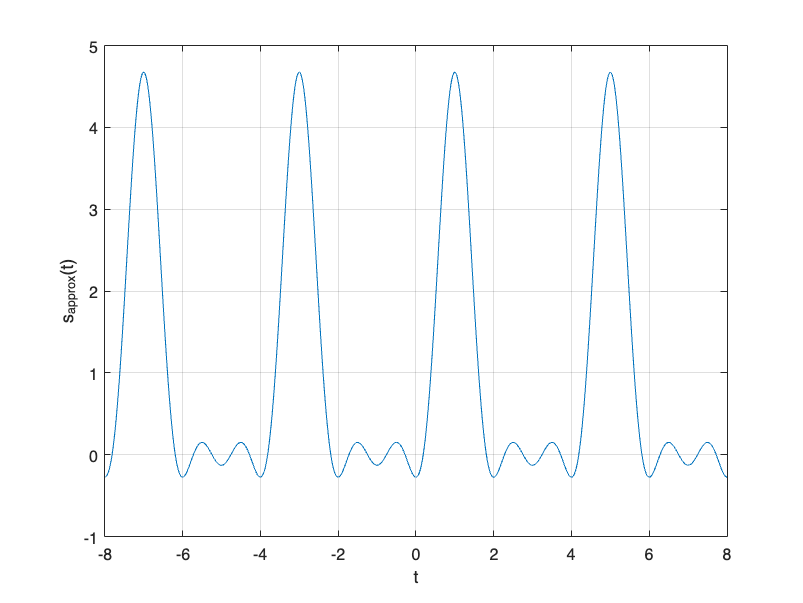

%Define the desired frequency range;
N = 100;
n_range = -N : N ;

%Define the fundamental frequency
T = 4 ;
omega0 = 2 * pi / T ;

%Calculate the Fourier series S(n)
S = exp( -j * n_range * pi / 2 ) .* ...
    sin( n_range * pi / 4 ) ./ ( n_range * pi / 4 ) ;
%L'hopital
index = find ( n_range == 0 ) ;
S(index) = 1 ;

%Calculate the magnitude and phase
magnitude = abs( S ) ;
phase = angle ( S ) ;

%plot the approximation

tmin = -2 * T ;
tmax = 2* T ;
dt = (tmax - tmin) / 2000 ;

t_range = tmin : dt : tmax ;
%Calculate the approximation.

L = length(t_range) ;
for tt = 1 : L
    t = t_range(tt) ;
    %Evaluate the FS sum
    summ = 0 ;
    nn = 1 ; %needed to address elements of array S
    for n = -N : N 
        summ = summ + S(nn) * exp(j * n * omega0 * t ) ;
        nn = nn + 1 ;
    end
    %Now the signal approximation
    sapprox(tt) = real(summ) ;
end

%PLOT
plot( t_range, sapprox )
xlabel('t')
ylabel('s_{approx}(t)')
grid on